
syms x y
u(x,y) = sin(5*x)*sin(1-x)*sin(2*y)

$$u(x, y) = -\sin\left(5\,x\right)\,\sin\left(x-1\right)\,\sin\left(2\,y\right)$$

f = -diff(u,x,2) -diff(u,y,2)

$$f(x, y) = 10\,\cos\left(5\,x\right)\,\cos\left(x-1\right)\,\sin\left(2\,y\right)-30\,\sin\left(5\,x\right)\,\sin\left(x-1\right)\,\sin\left(2\,y\right)$$

g0 = 0

g0 =        0       


gy = diff(u,y)

$$gy(x, y) = -2\,\cos\left(2\,y\right)\,\sin\left(5\,x\right)\,\sin\left(x-1\right)$$

gx = diff(u,x)

$$gx(x, y) = -5\,\cos\left(5\,x\right)\,\sin\left(x-1\right)\,\sin\left(2\,y\right)-\cos\left(x-1\right)\,\sin\left(5\,x\right)\,\sin\left(2\,y\right)$$

a1 = subs(gy, y, 1)

$$a1(x, y) = -2\,\sin\left(5\,x\right)\,\sin\left(x-1\right)\,\cos\left(2\right)$$

a2 = subs(-gy, y,0)

$$a2(x, y) = 2\,\sin\left(5\,x\right)\,\sin\left(x-1\right)$$

a3 = subs(gx,y, 1)

$$a3(x, y) = -5\,\cos\left(5\,x\right)\,\sin\left(x-1\right)\,\sin\left(2\right)-\cos\left(x-1\right)\,\sin\left(5\,x\right)\,\sin\left(2\right)$$

%plot 3d
[X,Y] = meshgrid(0:0.01:1,0:0.01:1);
Z = sin(5*X).*sin(1-X).*cos(pi/2*(3-3*Y));

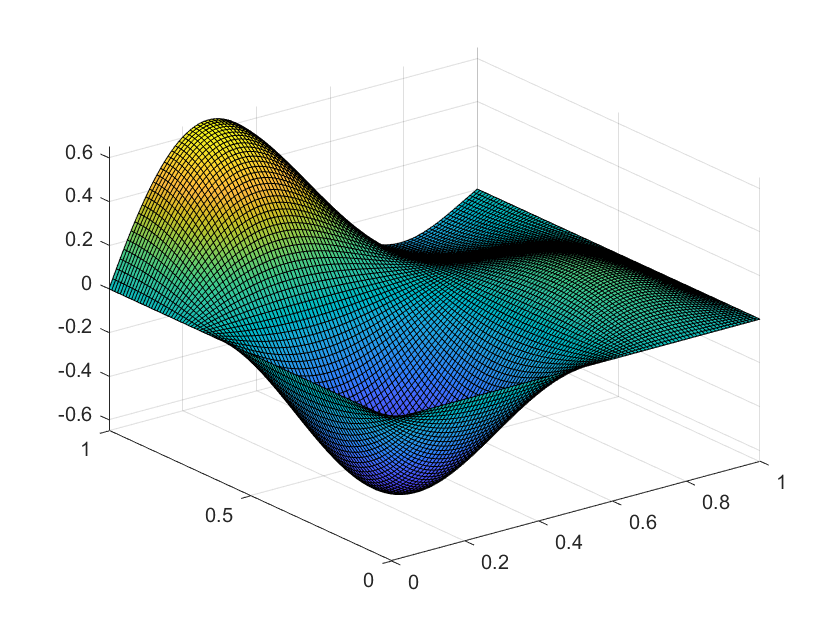

surf(X,Y,Z)